#  Geostatistika 05

format compact;

**Úloha 1.   ** Vytvořte funkci `primka` a spusťte s parametry xd=[1,3], zd=[10,20]. Vstupní vektor udává místa, kde se vypočtou hodnoty bodů na přímce. Zadáte-li např. x=[0,4], zobrazí se přímka v tomto rozsahu.

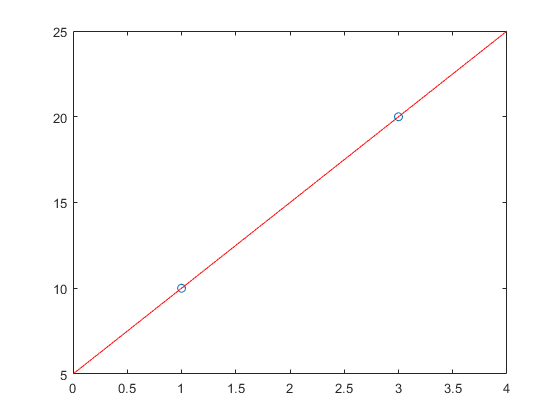

primka([1,3], [10,20], [0,4]);

## **Metoda nejmenších čtverců**

(více informací viz předchozí lekce)

Metoda nejmenších čtverců (ang. *least square method*) je aproximační metoda, kdy hledaná funkce **nemusí **procházet zadanými body. Předem stanovíme typ funkce který hledám.

- **lineární aproximace,** hledáme funkci ve tvaru $z = b + ax$

- **kvadratická aproximace**,hledáme funkci ve tvaru $z = a + bx + cx^2$

- **exponenciální aproximace**, hledáme funkci ve tvaru $z = l . a^x$ nebo $z = k + l . a^x$

### **Lineární aproximace metodou nejmenších čtverců**

Jsou dány body $[x_1, z_1]$, $[x_2,z_2]$ až $[x_n, z_n]$. Hledáme funkci ve tvaru $z = b + ax$, která aproximuje tyto body.

Vzorec $z_i = a + bx + e_i$ vyjadřuje, že pro danou souřadnic $x_i$, získáme její z-tovou souřadnici z rovnice přímky plus přičteme náhodnou odchylku $e_i$. Tyto náhodné odchylky jsou **vzájemně nezávislé.**

Hledáme minimální součet reziduí $S = \sum_{i=1}^n [z_i - (a + bx_i)]^2 = min$, které najdeme tak, že položíme její parciální derivace podle $a$ a $b$ rovné nule.

$\partial_a S = 0, \quad \partial_b S = 0$.

**Úloha 2.    **Spočtěte parciální derivace podle proměnných $a$ a $b$ a určete tzv. normální rovnice.

$\partial_a S = \sum_{i=1}^n 2(z_i - a - bx_i)  (- 1)$,

$\partial_b S = \sum_{i=1}^n 2(z_i - a + bx_i] (- x_i)$.

(Použili jsme metodu pro derivaci složené funkce)

Pokud se to povedlo odvodili jste tzv. normální rovnice. Jejich zápis, resp. zápis levé a pravé strany soustavy v MATLAB by mohl být následující, kdy graf by měl vypadat jako v předchozím případě.

xs = [1, 3];
zs = [10, 20];
x  = [0, 4];

ns = length(xs);

L = [ns      sum(xs); 
     sum(xs) sum(xs.*xs)
    ];

P = [sum(zs) sum(xs.*zs)]';

B = inv(L) * P;

a = B(1);
b = B(2);

z = a + b * x;

figure;
plot(xs, zs, 'o');
hold on;
plot(x, z, 'r-');

**Úloha 3.   **Funkci `primka` uložte jako `primka_LSQ`. Výše uvedenými třemi příkazy nahraďte tu část, kterou jsme dříve vyznačili žlutě. Doplňte data o třetí bod označený v obrázku výše šipkou a funkci spusťte.

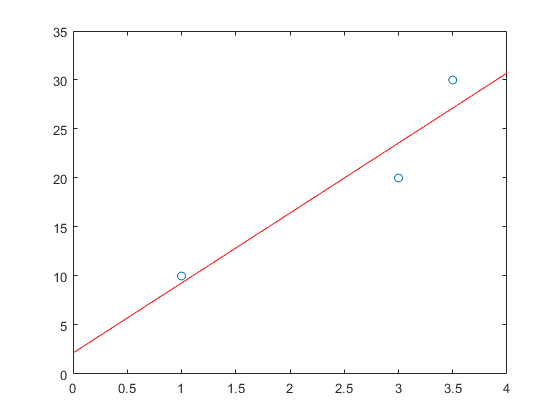

primka_LSQ([1, 3, 3.5], [10, 20, 30], x);

**Úloha 4.    **Vyzkoušejte spuštění funkce na libovolná data obsahující více bodů a také na data sestávající pouze ze dvou bodů z úlohy 1.

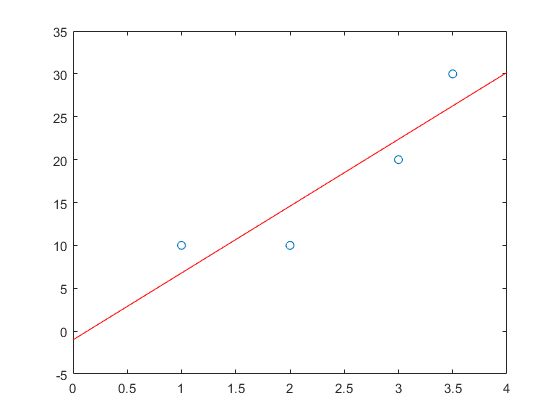

primka_LSQ([1, 2, 3, 3.5], [10, 10, 20, 30], x);

primka_LSQ([1, 3], [10, 20], x);

### Základní vzorec lineární regrese


$$B = (X' X)^{-1}X'z$$


... bude doplěno o poznámky

**Úloha 5.    **Podívejte se do funkce, primka_LSQ, kterou jsem vám zaslal minule, a najděte tam řádek, kde je regresní matice vytvořena. Spusťte funkci primka_LSQ na stejná data jako v U3 a ověřte, že dává stejné výsledky.

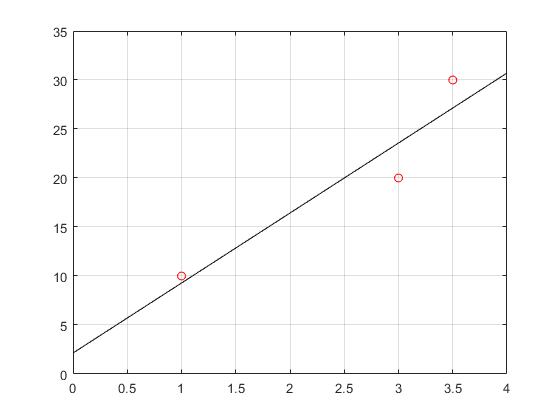

primka_LSQ_v1([1, 3, 3.5], [10, 20, 30], x);

Zdá se, že funkce dává stejné výsledky.

**Úloha 6.    **Na následujícím obrázku je trojice bodů proložených dvěma přímkami (jen 3 body, aby se to snadno spočítalo). Napište rovnice obou přímek a zjistěte, která z nich vystihuje data lépe ve smyslu metody nejmenších čtverců.

U červené přímky vidíme, že prochází např. body $[-1,0]$ a $[1,1]$, směrnice je tedy $b = 1/2$ a úsek $a = 1/2$ tzn. $z = 0.5 + 0.5x$.

U modré přímky vidíme, že prochází např. body $[0,0]$ a $[2,2]$, směrnice je tedy $b = 2/2 = 1$ a úsek $a$ = 0 tzn. $z = x$.


$$RSS_{R} =\sum e_i^2 = (-1/2)^2 + 1^2 + (-1/2)^2 = 1/4 + 4/4 + 1/4 =  6/4 = 3/2 = 1.5$$



$$RSS_B = \sum e_i^2 = 0^2 + 1^2 + (-1)^2 = 2$$


Protože suma reziduí je menší pro červenou přímku, pak tato lépe aproximuje zadané body.

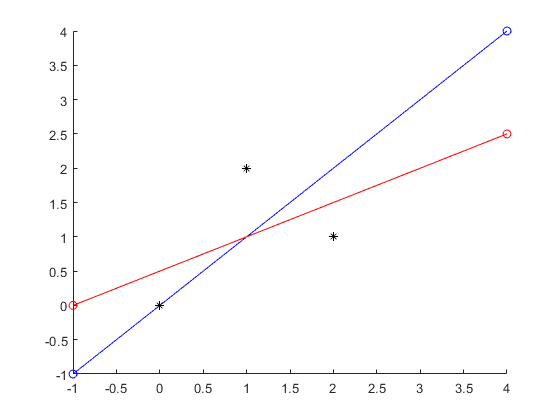

figure;
hold on;

A = [-1 4];
B = [-1 4];
plot(A, B, 'bo');
axis([-1 4 -1 4]);
plot(A, B, 'b-');

C = [-1 4];
D = [0 2.5];
plot(C, D, 'ro');
plot(C, D, 'r-');

plot([0 1 2], [0 2 1], 'k*')

hold off;

**Zpracování a studium mi trvalo asi 3h. Otázky žádné nemám, musím po nemoci dodělat cvičení 3 a 4, které Vám pošlu záhy. Pěkný den přeji.**